# Replicating figures with event detection

ntype = 'HD_gamma';

export = @(name) Utils.printto(['figures_on_events_' ntype], name);

## PLS plots

d = SessManager.load_special('Mouse2022', ntype);
alpha = 0.02;

[X, ks] = d.get_dataset;
X_shuf = shuffle(X, ks);
X_z = zscore(X);
X_shuf_z = zscore(X_shuf);
[XS, stats, origin] =...
    Utils.pls_short(X_z, [ceil(ks/2), mod(ks,2)]);
XS_s = (X_shuf_z - mean(X_shuf_z)) * stats.W;
origin_s = -mean(X_shuf_z) * stats.W;

Using one session from Mouse2022, showing real data:

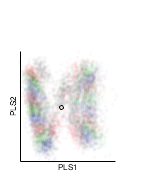

figure;
scatter(XS(:,1), XS(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin(1), origin(2), 10, 'k');
xlabel PLS1
ylabel PLS2
axis equal; 
axis tight;
xl_ = xlim;
yl_ = ylim;
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);
export('PLS_events_real.pdf');

And shuffled data:

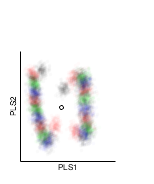

figure;
scatter(XS_s(:,1), XS_s(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin_s(1), origin_s(2), 10, 'k');
xlabel PLS1;
ylabel PLS2;
axis equal;
axis tight;
xlim(xl_);
ylim(yl_);
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);
export('PLS_events_shuf.pdf');

## Decoding curves

save_file = sprintf('decoding_curves_fits_%s.mat', ntype);

if ~exist(save_file, 'file')
    dbfile = sprintf('decoding_all_sess_%s.db', ntype);
    conn = sqlite(dbfile);
    samp_size = 80;
    %[sess, mouse_names] = DecodeTensor.filt_sess_id_list;
    [sess, mouse_names] = SessManager.usable_sess_id_list;
    sess = cellfun(@(a,b) {a,b}, mouse_names, sess, 'UniformOutput', false);
    [n_sizes, imse, mask] = PanelGenerator.db_imse_reader_safe(conn, 'unshuffled', sess, samp_size);
    [n_sizes_s, imse_s, mask_s] = PanelGenerator.db_imse_reader_safe(conn, 'shuffled', sess, samp_size);
    [n_sizes_d, imse_d, mask_d] = PanelGenerator.db_imse_reader_safe(conn, 'diagonal', sess, samp_size);
    assert(isequal(n_sizes, n_sizes_s), 'mismatch between unshuffled and shuffled sampling');
    assert(isequal(n_sizes, n_sizes_d), 'mismatch between unshuffled and diagonal sampling');
    
    [series_fits{1}, series_gof{1}] = Utils.cf_p2(2,@(n,m)createFit_infoSaturation(n(:),mean(m)'), n_sizes, imse);
    progressbar(1/3/2);
    [series_fits{2}, series_gof{2}] = Utils.cf_p2(2,@(n,m)createFit_infoSaturation(n(:),mean(m)'), n_sizes, imse_s);
    progressbar(2/3/2);
    [series_fits{3}, series_gof{3}] = Utils.cf_p2(2,@(n,m)createFit_infoSaturation(n(:),mean(m)'), n_sizes, imse_d);
    progressbar(3/3/2);
    [series_exp_fits{1}, series_exp_gof{1}] = Utils.cf_p2(2,@(n,m)createFit_exp(n(:),mean(m)'), n_sizes, imse);
    progressbar(4/3/2);
    [series_exp_fits{2}, series_exp_gof{2}] = Utils.cf_p2(2,@(n,m)createFit_exp(n(:),mean(m)'), n_sizes, imse_s);
    progressbar(5/3/2);
    [series_exp_fits{3}, series_exp_gof{3}] = Utils.cf_p2(2,@(n,m)createFit_exp(n(:),mean(m)'), n_sizes, imse_d);
    progressbar(6/3/2);
    
    [I0_fit, I0_conf] = Utils.fit_get(series_fits{1}, 'I_0');
    [I0_fit_s, I0_conf_s] = Utils.fit_get(series_fits{2}, 'I_0');
    [I0_fit_d, I0_conf_d] = Utils.fit_get(series_fits{3}, 'I_0');
    
    [N_fit, N_conf] = Utils.fit_get(series_fits{1}, 'N');
    [N_fit_s, N_conf_s] = Utils.fit_get(series_fits{2}, 'N');
    [N_fit_d, N_conf_d] = Utils.fit_get(series_fits{3}, 'N');
    
    save(save_file, 'sess', 'mouse_names', 'n_sizes',...
        'imse', 'imse_s', 'imse_d', 'series_fits', 'series_gof', 'I0_fit', 'I0_conf',...
        'I0_fit_s', 'I0_conf_s', 'N_fit', 'N_conf',...
        'N_fit_s', 'N_conf_s', 'series_exp_fits', 'series_exp_gof',...
        'I0_fit_d', 'I0_conf_d', 'N_fit_d', 'N_conf_d');
else
    load(save_file);
end

r2 = cellfun(@(x)x.rsquare, series_gof{1});
r2_s = cellfun(@(x)x.rsquare, series_gof{2});
r2_d = cellfun(@(x)x.rsquare, series_gof{3});

r2_exp = cellfun(@(x)x.rsquare, series_exp_gof{1});
r2_s_exp = cellfun(@(x)x.rsquare, series_exp_gof{2});
r2_d_exp = cellfun(@(x)x.rsquare, series_exp_gof{3});

fprintf('Unshuf R^2: %f - %f, median: %f\n', min(r2), max(r2), median(r2));

Unshuf R^2: -295.033782 - 0.998848, median: 0.996263


fprintf('Shuf R^2: %f - %f, median: %f\n', min(r2_s), max(r2_s), median(r2_s));

Shuf R^2: -549.545507 - 0.998204, median: 0.983064


fprintf('Diag R^2: %f - %f, median: %f\n', min(r2_d), max(r2_d), median(r2_d));

Diag R^2: -375.048525 - 0.998908, median: 0.994512


fprintf('Unshuf (exp) R^2: %f - %f, median: %f\n', min(r2_exp), max(r2_exp), median(r2_exp));

Unshuf (exp) R^2: -10.405549 - 0.999201, median: 0.996119


fprintf('Shuf (exp) R^2: %f - %f, median: %f\n', min(r2_s_exp), max(r2_s_exp), median(r2_s_exp));

Shuf (exp) R^2: -17.633446 - 0.998208, median: 0.981333


fprintf('Diag (exp) R^2: %f - %f, median: %f\n', min(r2_d_exp), max(r2_d_exp), median(r2_d_exp));

Diag (exp) R^2: -12.362007 - 0.999156, median: 0.181989


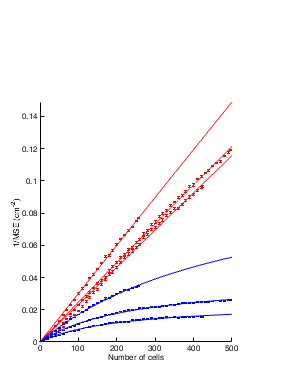

selected_indices = SessManager.special_sessions_usable_index({'Mouse2022', 'Mouse2024', 'Mouse2028'});
s_inds = selected_indices;

figure;
PanelGenerator.plot_decoding_curve(sess, s_inds, n_sizes, imse_s, I0_fit_s, N_fit_s, 'r', false);
PanelGenerator.plot_decoding_curve(sess, s_inds, n_sizes, imse, I0_fit, N_fit, 'b', false);
xlabel 'Number of cells'
ylabel '1/MSE (cm^{-2})'
ylim([0 Inf]);
figure_format([2 2.5]);
export('decoding_events.pdf');

## Signal and noise

get_usable_result = @(idx) load(onefile(['records_adjacent_metrics_' ntype '/*_' num2str(idx, '%.3d') '_*']));

res = cell(1,numel(s_inds));
for s_ix = 1:numel(s_inds)
    res{s_ix} = get_usable_result(s_inds(s_ix));
end

cutoff = 100;
asymp_line = @(n,m) Utils.fitaline(n,m,cutoff);
res_lookup = @(res, code)...
    cellfun(@(x)...
    cellfun(@(y)...
    median(y{code(1),code(2:3)}),...
    x.results_table),...
    res,'UniformOutput',false);


n = cellfun(@(x)x.n_sizes, res, 'UniformOutput', false);
signal = res_lookup(res, 'mse');
noise = res_lookup(res, 'mce');
noise_shuf = res_lookup(res, 'mue');

snr = cellfun(@rdivide, signal, noise,...
    'UniformOutput', false);
snr_shuf = cellfun(@rdivide, signal, noise_shuf,...
    'UniformOutput', false);

[signal_slope, signal_slope_conf] = cellfun(asymp_line, n, signal,...
    'UniformOutput', false);
[noise_slope, noise_slope_conf] = cellfun(asymp_line, n, noise,...
    'UniformOutput', false);
[noise_shuf_slope, noise_shuf_slope_conf] = cellfun(asymp_line, n, noise_shuf,...
    'UniformOutput', false);

[asymp_snr, asymp_snr_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_slope, noise_slope_conf);
[asymp_snr_shuf, asymp_snr_shuf_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_shuf_slope, noise_shuf_slope_conf);

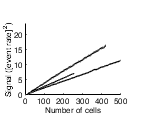

dff2_lim = [0 24];
figure;
MultiSessionVisualizer.plot_single_filtered(n, {signal}, {'k'}, [true true true]);
ylim(dff2_lim);
xlabel 'Number of cells'
ylabel 'Signal ([event rate]^2)'
figure_format([1 0.75]);
export('signal_events.pdf');

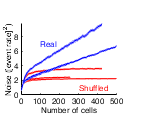


figure;
MultiSessionVisualizer.plot_single_filtered(n, {noise_shuf, noise}, {'r', 'b'}, [true true true]);

text(100, 7, 'Real', 'Color', 'b');
text(300, 1, 'Shuffled', 'Color', 'r');
xlabel 'Number of cells'
ylabel 'Noise ([event rate]^2)'
figure_format([1 0.75]);
export('noise_events.pdf');

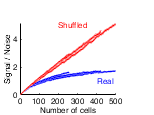


figure;
MultiSessionVisualizer.plot_single_filtered(n, {snr, snr_shuf}, {'b', 'r'}, [true true true]);
text(200, 5, 'Shuffled', 'Color', 'r');
text(400, 1, 'Real', 'Color', 'b');
xlabel 'Number of cells'
ylabel 'Signal / Noise'
figure_format([1 0.75]);
export('snr_events.pdf');

function [quotient, quotient_uncertainty] = uncertain_divide(x, xc, y, yc)
quotient = x./y;
quotient_uncertainty = abs(x./y)*sqrt((xc./x).^2 + (yc./y).^2);
end